# ACM 11: Week 7 In-class Exercise 2

**(0) Please include all the names of your group members here: Kyle McGraw, Dallas Taylor**

## Predicting stock market with the Monte-Carlo method 

In this exercise we will see how the Monte Carlo method can be used to help us predict the stock market. While we do not know how stocks will evolve over time, we can use a mathematical model to predict different potential stock trajectories. The code below calls a function which solves a stochastic differential equation (SDE, you can think of this as an ODE with a random input) to generate many possible stock trajectories over a 12-month period. The output, $y$, that we are interested in is the final value of the stock price at the end of that 12-month period. The inputs $x$ that generate different $y$ are the random inputs to the SDE. You can interpret these random inputs as events that might make a stock price go up or down.

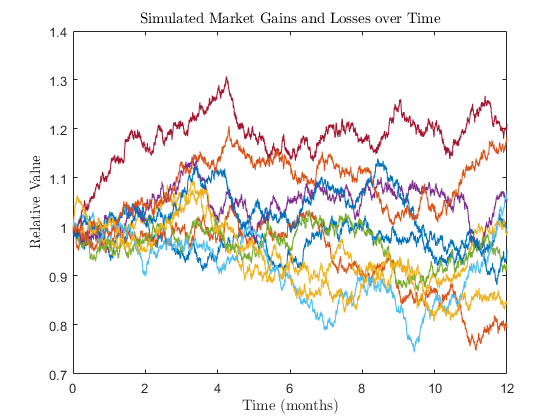

close all 
clear; clc;

dt = 0.001;
t = 0:dt:12;

% call getStockTraj to generate possible stock trajectories and
% visualize the results
N = 1000;
S = getStockTraj(t,N);

figure(1);
plot(t,S(:,1:10));  % only plot the first 10.
xlabel('Time (months)','interpreter','LaTex');
ylabel('Relative Value','interpreter','LaTex');
set(gca,'fontsize',10);
title('Simulated Market Gains and Losses over Time','interpreter','LaTex');

**(1) We are interested in the mean gain/loss of the stock at the final time. A value greater than 1 indicates a simulation in which the stock price as increased. A value lower than 1 indicates a simulation in which the stock price as decreased. In the code block below, calculate the sample mean gain/loss at the final time based on the 10 samples we generated above. **(The way the code is set-up, the last row of the output of getStockTraj is the final time).

mu_S = mean(S(end,:));

**(2) Because our simulation is random, we will get a different estimate every time we run it. In the code block below, use a for loop to generate 90 different Monte Carlo estimates of the stock price gain/loss. That is, you will want to generate 100 independent sets of N  trajectories, and calculate the sample means of each one. Then, plot a histogram of the estimates.**

**Note: this may be a bit slow, so start with N = 10 before trying N = 100. **You can ignore the loss_prob variable for now.

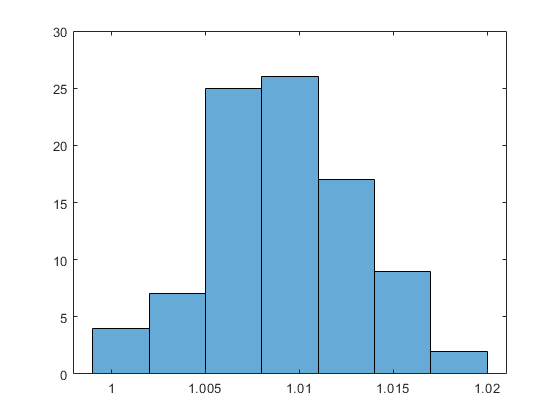

estimates = zeros(90,1);
loss_prob = zeros(90,1);

for j = 1:90
    % TODO for Problem 2: fill in estimates with different MC estimates
    S = getStockTraj(t,N);
    estimates(j) = mean(S(end,:));
    
    %TO-DO for Problem 4
    loss_prob(j) = mean(S(end,:)<0.8); 
end

figure(2);
histogram(estimates)

**(3) How does the histogram of the 90 different estimates vary as the number of samples used per estimate, **N**, is varied? Look carefully at the highest and lowest values of the estimate.**

**As we increase N, the histogram narrows with the highest and lowest values of the estimate getting closer together.**

**(4) Now, we want to know what the probability is that our stock will lose more than 20% of its value 12 months from now. This happens if the final value of a stock is less than 0.8 times its starting value of 1. In the code block above, use the predicted stock trajectories to calculate this probability of losing more than 20% of its value. **Hint: Remember that this probability is just the mean of the indicator function that is 1 if the final stock value is less than 0.8 and 0 otherwise. You can use S(end,:)<0.8 to get a vector of the indicator function values.

**(5) In the code block below, plot a histogram of the estimates of the probability that our stock will lose 20% of its value.**

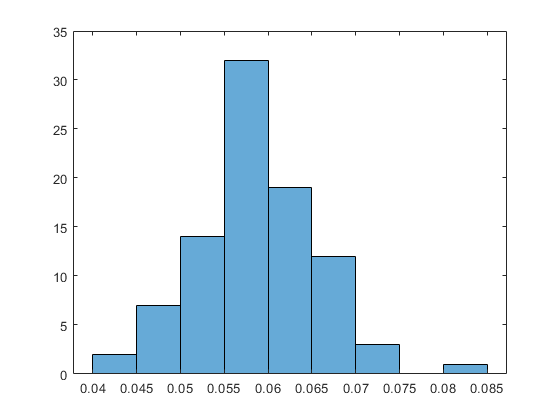

figure(3);
histogram(loss_prob)

This function below generates N independent stock simulations over the time period t.

function S = getStockTraj(t,N)
    % Set parameters
    mu1 = 0.001; sigma = 0.05;
    mu2 = 0.05; 
    
    dt = t(2) - t(1);
    S = zeros(length(t),N); 
    S(1,:) = 1;
    
    % Simulate the stock market
    for i = 1:length(t)-1
       x = randn(1,N); % generate random events
       S(i+1,:) = S(i,:) + dt*(mu1*S(i,:)+mu2*(1-S(i,:)))+sigma*sqrt(dt)*x;
    end
end